# Sessió 9

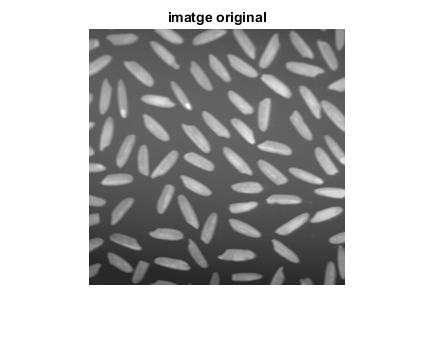

clear,close all
orig = imread ('arros.tif');
imshow(orig), title('imatge original')

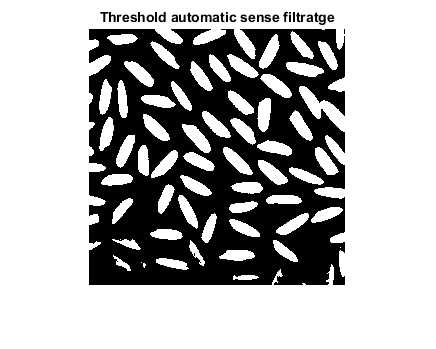

% segmentem per binarització
bw=im2bw(orig, graythresh(orig)); % Binarització per Otsu
figure, imshow(bw),title('Threshold automatic sense filtratge')

No funciona, perdem grans. No confieu mai en els detectors automatics de llindar.

El problema està en que la iluminació no és gens homogènea

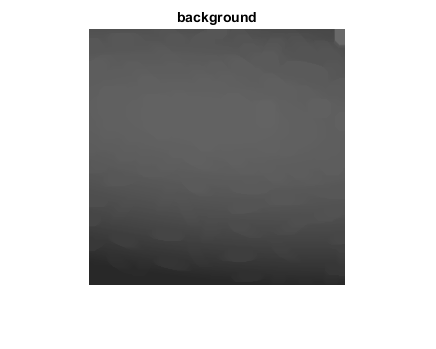

% Fem un filtratge morfològic
bg = imopen(orig,strel('disk',10));
figure, imshow(bg),title('background')

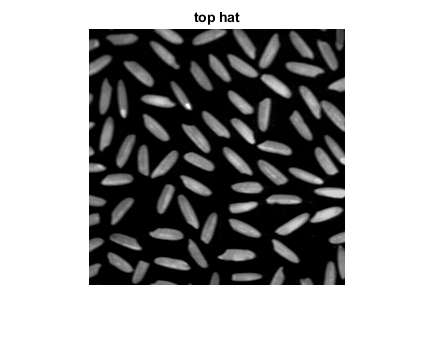

figure, surf(bg) % mostrem el background com si fos una superfície
%Li restem el background a la imatge
y = imsubtract(orig,bg);
figure, imshow(y, []), title('top hat')

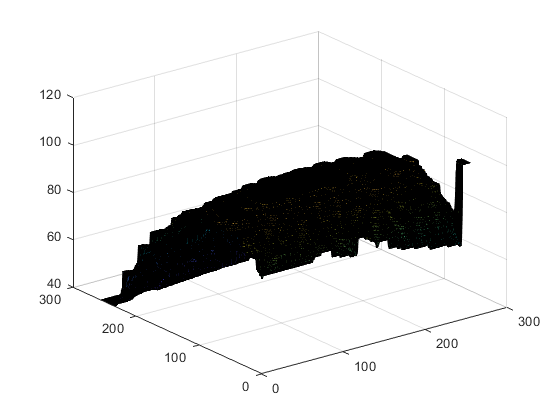

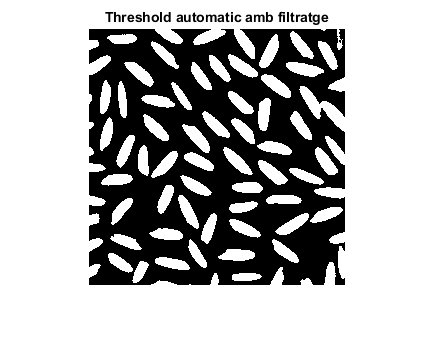

% tornem a segmentar per Otsu
bw=im2bw(y, graythresh(y));
figure, imshow(bw),title('Threshold automatic amb filtratge')

Ara si!

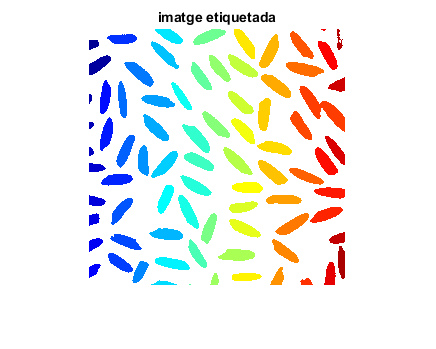

% etiquetem la imatge segmentada
[eti num] = bwlabel(bw,4);
figure,imshow(label2rgb(eti)), title('imatge etiquetada')

% Comptem ara el nombre d’objectes a la imatge
num

num = 81

%o be:
max(eti(:))

ans = 81

% obtenim descriptors de les regions
Dades=regionprops(eti,'all');

Comproveu en el workspace la variable Dades. 

Quines propietats hem extret de cada regió?

Hem extret moltes propietats, per ser específics totes aquestes: Àrea, centroid, BoundingBox, SubarrayIdx, MajorAxisLength, MinorAxisLength, Eccentricity, Orientation, ConvexHull, ConvexImage, ConvexArea, Circularity, Image, FilledImage, FilledArea, EulerNumber, Extrema, EquivDiameter, Solidity, Extent, PixelIdxList, PixelList, Perimeter, PerimeterOld, MaxFeretDiameter, MaxFeretAngle, MaxFeretCoordinates, MinFeretDiameter,  MinFeretAngle, MinFeretCoordinates. Hi han tantes propietats perquè s'ha fet servir la opció all, però si es voldrien només algunes determinades es podria fer servir basic (`'Area', 'Centroid', 'BoundingBox').`

Amb aquestes dades podem calcular centroids en x i y utilitzant la propietat centroids i la funció cat amb una de les dues components a 1, calcular el centre d'objectes circulars amb Major i MinorAxisLength, entre altres.

https://es.mathworks.com/help/images/ref/regionprops.html

Consulteu el help de la funció regionprops.

% Podem obtenir una dada de l’objecte 50 de la forma:
Dades(50).Area

ans = 305

% O be un vector amb totes les Àrees:
Arees=[Dades.Area];

Exercici: en la imatge segmentada, separeu els grans d’arròs que es toquen. Desprès elimineu els grans d’arròs que toquen les vores. Tots aquests grans falsejaven el resultat. 

Amb la nova imatge etiquetatda, obteniu les propietats que us semblin adients usant regionprops.

Representeu mitjançant plots o diagrames de barres aquelles propietats que us semblin interessants per a fer un control de qualitat dels grans d’arròs.